# Simulate and Verify AUTOSAR Component Behavior by Using Diagnostic Fault Injection

This example shows how to simulate and verify the behavior of AUTOSAR components modeled in Simulink® that contain calls into the AUTOSAR Diagnostic Event Manager (Dem). You can gain quick testing coverage by overriding the diagnostic status of specific events or verify component recovery by injecting transient event failures.

## Override AUTOSAR Diagnostic Statuses to Gain Coverage

Component models often call into the AUTOSAR Diagnostic Event Manager (Dem) to communicate localized errors to the rest of the system. They may also query the diagnostic status of other systems by making calls to getEventStatus.

To show how to simulate and verify behavior by overriding the status of events, an example throttle position monitor component is shown. This component contains four calls to the Diagnostic Event Manager to query if four specific events have failed on their last evaluation. The status of these events determines if the primary and seconday sensor inputs can be passed on to the rest of the system. If both sensors report event failures, then a default value is passed on as the sensor input and a setEventStatus call reports a general failure to the system.

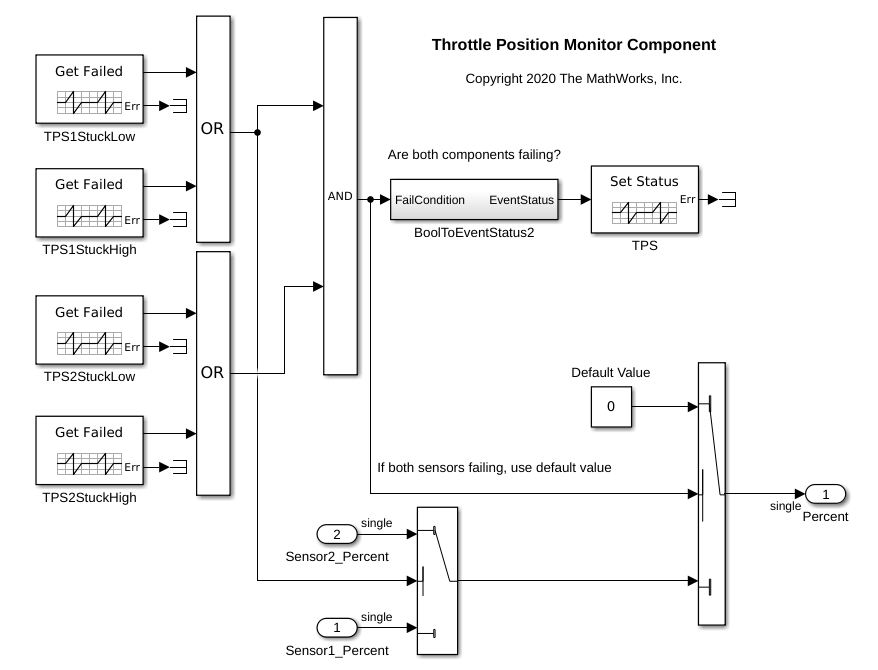

To verify that this component works as designed, a test harness model capable of exercising the branches of the model is shown below. In the test harness, the values 1 and 2  distinguish the two sensor inputs and a Diagnostic Service Component block provides simulation for calls to GetEventFailed and SetEventStatus. The Dem Status Override blocks are then added to override the Test Failed bit of the UDS status byte for each event. 

open_system('autosar_bsw_override_test');

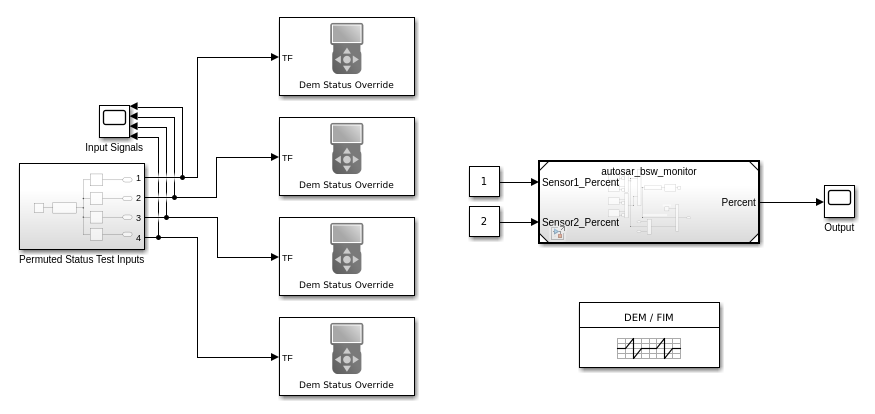

To get a more visual understanding of the test conditions and coverage for the example component in the test harness, from the Apps gallery, you can use the **Coverage Analyzer** app.

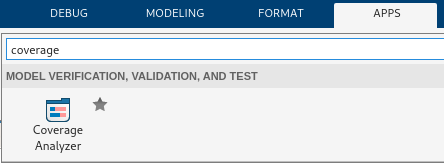

The view below shows the test coverage of the component model when the Dem Status Override blocks are removed. Given that the GetEventFailed calls returns false without external input, you are not able to achieve full decision coverage on the Switch blocks in the component. 

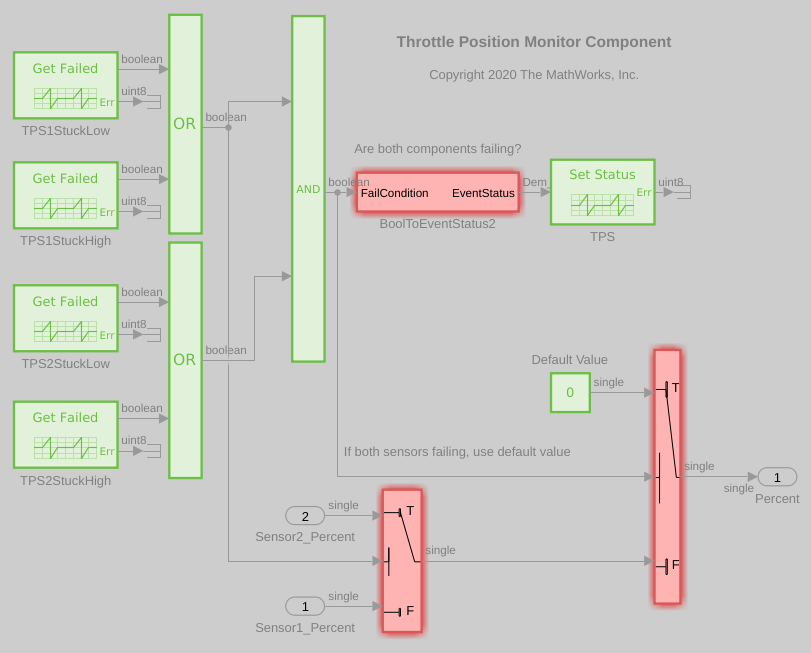

When Dem Status Override blocks are used in the harness, you are able to obtain full coverage of the component.

 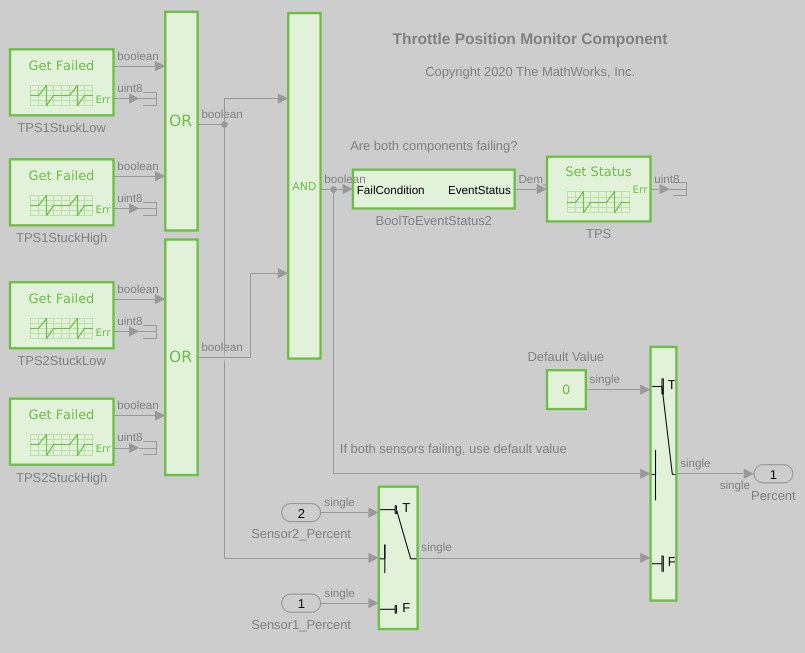

This example has shown how to obtain testing coverage by using the Dem Status Override block. While this specific example was narrow in scope, and it focused on the Test Failed bit, you can use the Dem Status Override block to configure each bit of the Unified Diagnostic Service (UDS) status byte to create any combination. 

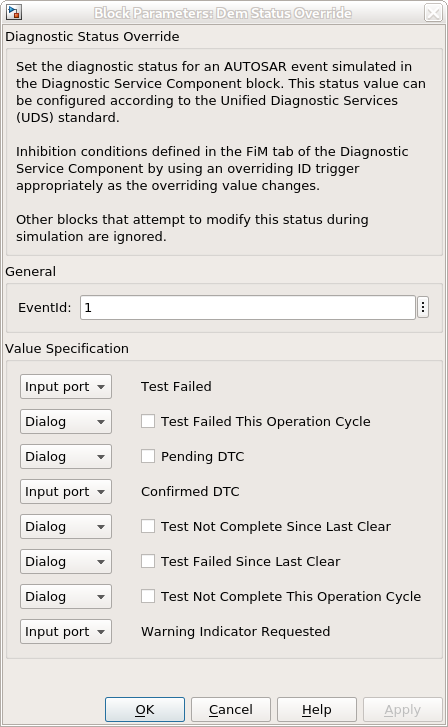

In general, you can use the Dem Status Override block to manually override the bits of the UDS status byte or have bits simulate independently. If you select `Dialog` and configure a bit, you override the status of that bit. Status bits are robust against changes with setEventStatus calls and the effects of event availability and operation cycle changes. Additionally, downstream services such as Function Inhibition (FiM) respond accordingly to the overridden status. If you select `Input port`, you allow certain status bits to update based on a connnected input signal, where values greater than zero turn the bit on. This functionality enables a component to override certains bits of a status while allowing others to continue to simulate independently. 

## Inject Transient Events to Verify Component Recovery

In AUTOSAR there are often component managing systems that are also responsible for monitoring their own status. In such systems, it is useful to be able to test if such a component can recover from faults to the point that it can again report success. For this type of testing, the Dem Status Override block used in the preceding example is not suitable beause it prevents the tested component from reporting a successful status again. Instead, a Dem Status Inject block can be used to create this type of test condition.

To show how to inject a transient event to verify component recovery, an example component for a regenerative parrticulate filter is shown. In this component, the state of the filter is stored in the state of a Delay block. During simulation, the filter incrementally increases within a nominal range of 20-80% utilization. This usage is monitored and reported to the diagnostic services. A representative regeneration mode is also shown. When regeneration is enabled the filter utilization quickly drops.

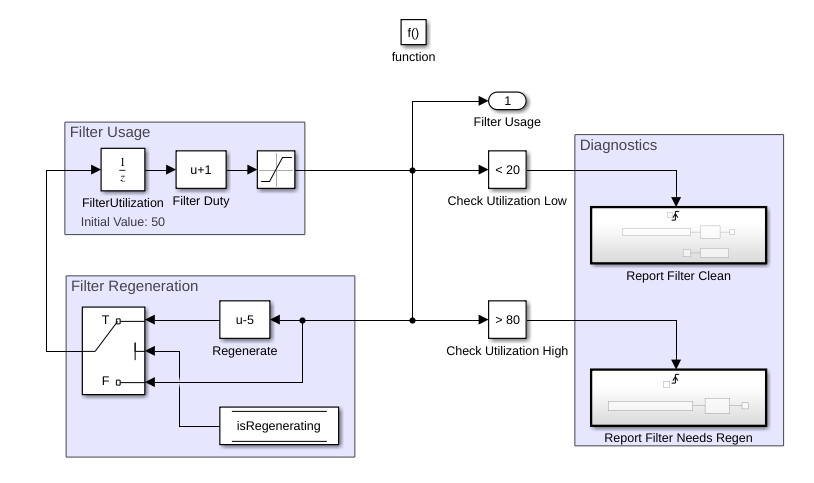

Within this component, the diagnostic services `Test Failed` bit is also queried. When a rising edge is detected, indicating that the filter has reached its threshold utilization, the component enters a regenration cycle by setting the *isRegenerating* Data Store to `true`.

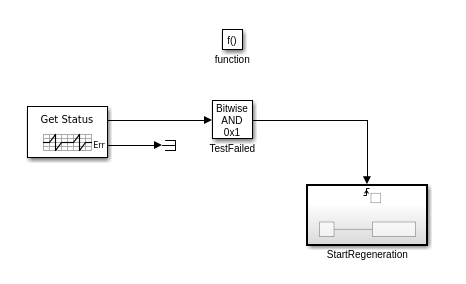

To verify the self recovery of this component, the test harness model shown was created. Specifically, you want to verify that the filter stays within the nominal range of utilization and that it enters and exits regeneration cycles correctly when diagnostic events occur. When the component simulates, it is expected to perpetually alternate between regeneration and nominal usage cycles by firing its own diagnostic events as required. You also want to test that the component can trigger a regeneration cycle if it receives a diagnostic event from the run-time environment (RTE). 

The test harness shows the component filter utilization with the gauge shown its dashboard. The Diagnostic Service Component block provides simulation for the calls to the Diagnostic Event Manager. When the harness simulates the component model, the gauge shows the filter gradually increase to 80% and then quickly lower to 20% as the filter is regenerated before repeating the cycle.

To verify that regeneration can be triggered from a diagnostic event provided by the RTE, you can use a Dem Status Inject block. The block has been specified to use `EventId 1,` which matches the client ports in the component defined in the Diagnsotic Service Component. The fault type has been set to `Event Fail `to set the `Test Failed` bit to true when the event is injected. In the test harness model, the failure injection can be triggered by using the dashboard button. Alternatively, you could have provided this failure through an input signal source for an automated test configuration. The test harness can simulate the component to show its response to the fault injection. You can see when a fault is injected by using the dashboard button because you can see the gauge drop even if it has not reached the upper threshold to show that the component model has entered a regeneration cycle. This example model is configured to run indefinitely, so you must click **Stop **to end the simulation.

open_system('autosar_bsw_inject_test');

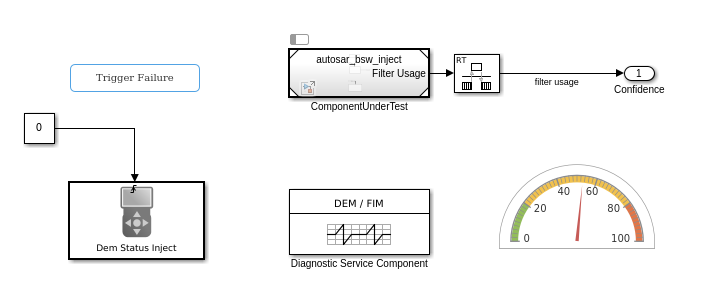

This example has shown how to test component recovery by using the Dem Status Inject block. While this specific example was narrow in scope, and it focused on the Test Failed bit, you can use the Dem Status Inject block to configure each bit of the Unified Diagnostic Service (UDS) status byte to create any combination. 

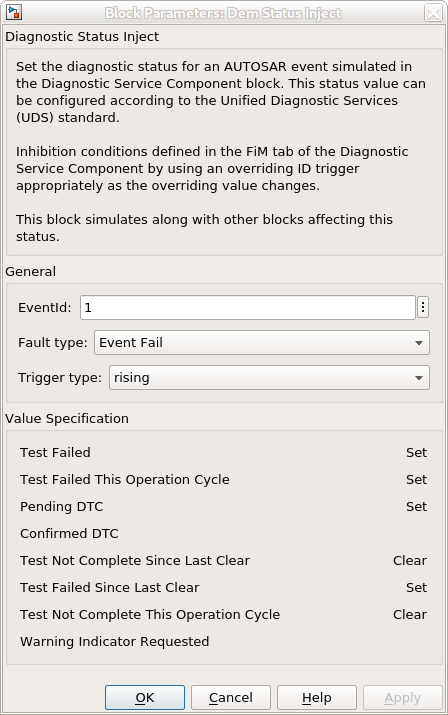

In general, you can use the Dem Status Inject block to manually override the bits of the UDS status byte. This block then simulates and updates its status with other blocks in the model to show recovery. Downstream services such as Function Inhibition (FiM) respond accordingly to this status throughout simulation.

*Copyright 2021 The MathWorks, Inc.*